## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath_ = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

2.1 Create ASSETCL plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_PlotNames, 'TR', '');

Set up **backtestPortfolio** **Method **properties

none (default) 

%            - rolling_w    (window)

%            - exp_decay    (tau)

%            - crisp        (alpha, z_target)       **NOTE**: z_target options 'mean' or 'latest'

%            - kernel       (h, gamma, z_target)

%            - e_pooling    (alpha, tau_prior, z_target)

%            - ew_ensemble  (alpha, tau_prior, z_target)

%            - cb_ensemble  (alpha, tau_prior, z_target,ensemble_wt_method)

## 3. Setting up HSFP object and Backtest object:

- Need to initialise backtestedPortfolio object (has built in defaults)

-  Initialise HSFPparameters object (has built in defaults)

- Need to provide Returns

- Assign HSFP parameters to backtestPortfolio

- Choose a method (defualt is 'None)

- If method is anything other than 'none' user needs to assign Signals Timetable

test_class1 = backtestedPortfolios;
HSFPparameters_test = HSFPparameters;
test_class1.HSFPparameters = HSFPparameters_test;
test_class1.Returns = M_Ret_TT;
test_class1.Method =  'none';
test_class1.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class1.HRPcashConstriant = 0;
test_class1.MVWts_lb = [0 0 0 0 0];
test_class1.MVWts_ub = [1 1 1 1 1];
test_class1.RegLambda = 0.005;
% test_class1.PSRbenchmark = "strategyWise";

 test1_bcktest = OOPbacktest_analysis(test_class1)
backtestPlot(test1_bcktest)

test1_bcktest.Attributions

**WINSOREISED** RETURNS

W_sd = 2;

test1_bcktest =   backtestedPortfolios with properties:

        PortfoliosList: {'EW (CM)'  'MVSR max'  'BalFund (BH)'  'HRP'  'BalFund (CM)'  'ALSI'  'ALBI'  'Cash'}
             AssetList: {'ALB_Index'  'FINI15_Index'  'INDI25_Index'  'RESI20_Index'  'Cash'}
          Attributions: [5×4 table]
    RollingPerformance: [152×8 timetable]
              HSFP_Prs: []
         NumPortfolios: 0
              DataType: "backtestedPortfolios"
         ExcessReturns: [151×5 double]
           GeometricSR: [1.6581 1.3993 1.7454 1.5688 1.8220]
            OptPortWts: {2×5 cell}
    Realised_tsPRet_TT: [152×8 timetable]
          WindowLength: 36
               Returns: [188×6 timetable]
               Signals: [189×1 timetable]
             RegLambda: 0.0050
              MVWts_lb: [0 0 0 0 0]
              MVWts_ub: [1 1 1 1 1]
     HRPcashConstriant: 0
                Method: "none"
        HSFPparameters: [1×1 HSFPpa

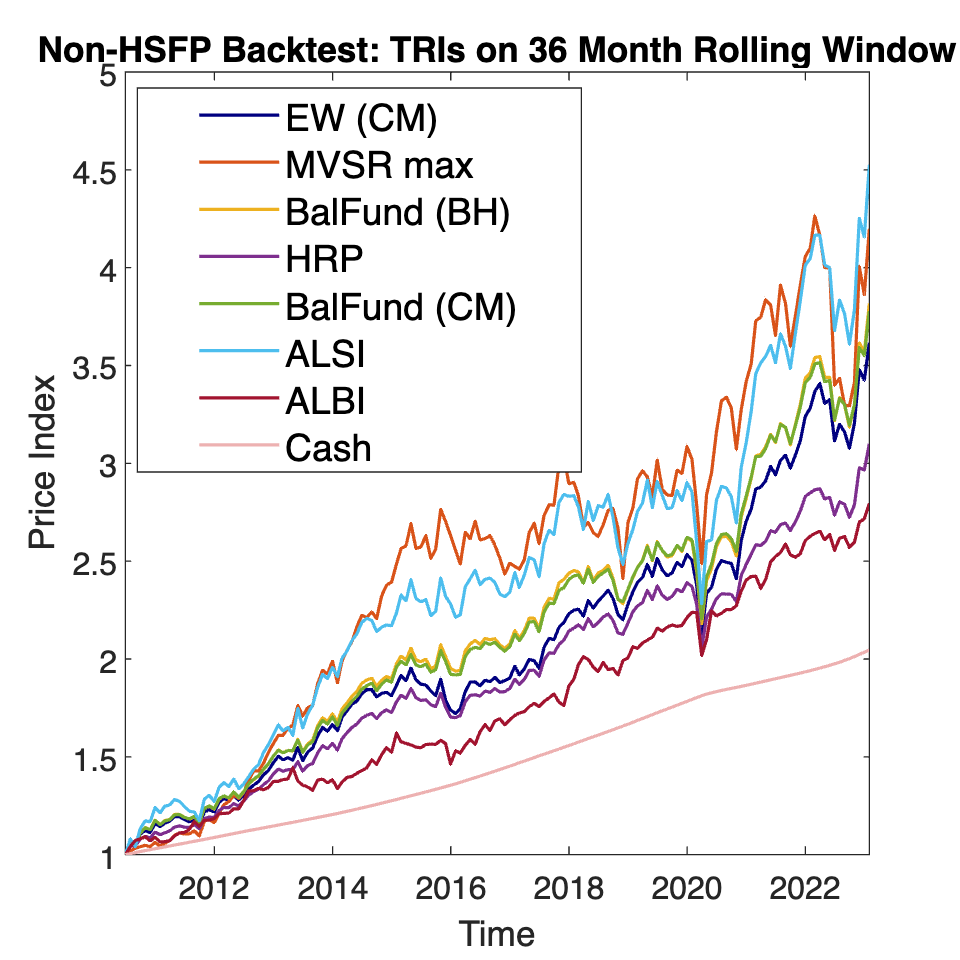

ans =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [1 1 1]
    Position: [100 100 600 600]
       Units: 'pixels'

  Show all properties


Return_matrix = table2array(M_Ret_TT);

[wx,b,ui,li] = winsorise(Return_matrix,W_sd);
winsorisedRet_TT = array2timetable(wx,'RowTimes',M_Ret_TT.Time);

ans = 5×4 table
                   Ann.Return    Ann.Risk    Ann.SR      PSR  
                   __________    ________    ______    _______

    EW              0.10758      0.096754    1.6581    0.99976
    MV              0.13177       0.15412    1.5561    0.99724
    BalFun (BH)     0.11233       0.10081    1.7454    0.99979
    HRP             0.11301       0.10794    1.6519    0.99935
    BalFun (CM)     0.11143      0.094951     1.822    0.99988


winsorisedRet_TT.Properties.VariableNames = M_Ret_TT.Properties.VariableNames;

test_class2 = backtestedPortfolios;
HSFPparameters_test = HSFPparameters;
test_class2.HSFPparameters = HSFPparameters_test;
test_class2.Returns = winsorisedRet_TT;
test_class2.Method =  'none';
test_class2.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class2.HRPcashConstriant = 1;
test_class2.MVWts_lb = [0 0 0 0 0];
test_class2.MVWts_ub = [1 1 1 1 0];
test_class2.RegLambda = 0.005;

 test2_bcktest = OOPbacktest_analysis(test_class2)
backtestPlot(test2_bcktest)

test2_bcktest.Attributions

returns_st1 = test_bcktest.Realised_tsPRet_TT.HRP; 
SIZE = numel(returns_st1);

% Create a histogram
histogram(returns_st1, SIZE/2, 'FaceColor', 'red');

test2_bcktest =   backtestedPortfolios with properties:

        PortfoliosList: {'EW (CM)'  'MVSR max'  'BalFund (BH)'  'HRP'  'BalFund (CM)'  'ALSI'  'ALBI'  'Cash'}
             AssetList: {'ALB_Index'  'FINI15_Index'  'INDI25_Index'  'RESI20_Index'  'Cash'}
          Attributions: [5×4 table]
    RollingPerformance: [152×8 timetable]
              HSFP_Prs: []
         NumPortfolios: 0
              DataType: "backtestedPortfolios"
         ExcessReturns: [151×5 double]
           GeometricSR: [1.9534 1.6968 1.9619 2.0518 2.0690]
            OptPortWts: {2×5 cell}
    Realised_tsPRet_TT: [152×8 timetable]
          WindowLength: 36
               Returns: [188×6 timetable]
               Signals: [189×1 timetable]
             RegLambda: 0.0050
              MVWts_lb: [0 0 0 0 0]
              MVWts_ub: [1 1 1 1 0]
     HRPcashConstriant: 1
                Method: "none"
        HSFPparameters: [1×1 HSFPpa

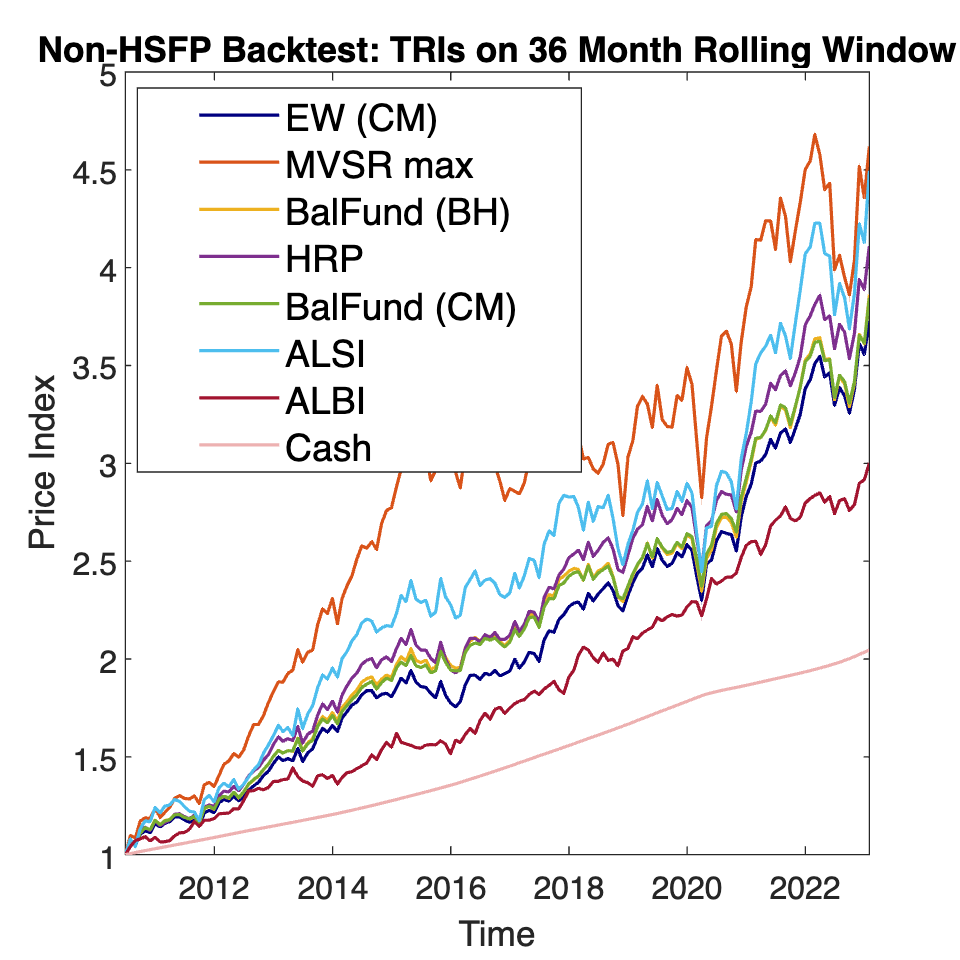

ans =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [100 100 600 600]
       Units: 'pixels'

  Show all properties


title('Strategy 1 returns distribution');


% Overlay the kernel density estimate

ans = 5×4 table
                   Ann.Return    Ann.Risk    Ann.SR      PSR  
                   __________    ________    ______    _______

    EW              0.11028      0.086647    1.9534    0.99999
    MV              0.12934       0.13661    1.6968    0.99894
    BalFun (BH)     0.11336       0.09141    1.9619    0.99998
    HRP             0.11889      0.096285    2.0518    0.99998
    BalFun (CM)     0.11298      0.086065     2.069    0.99999


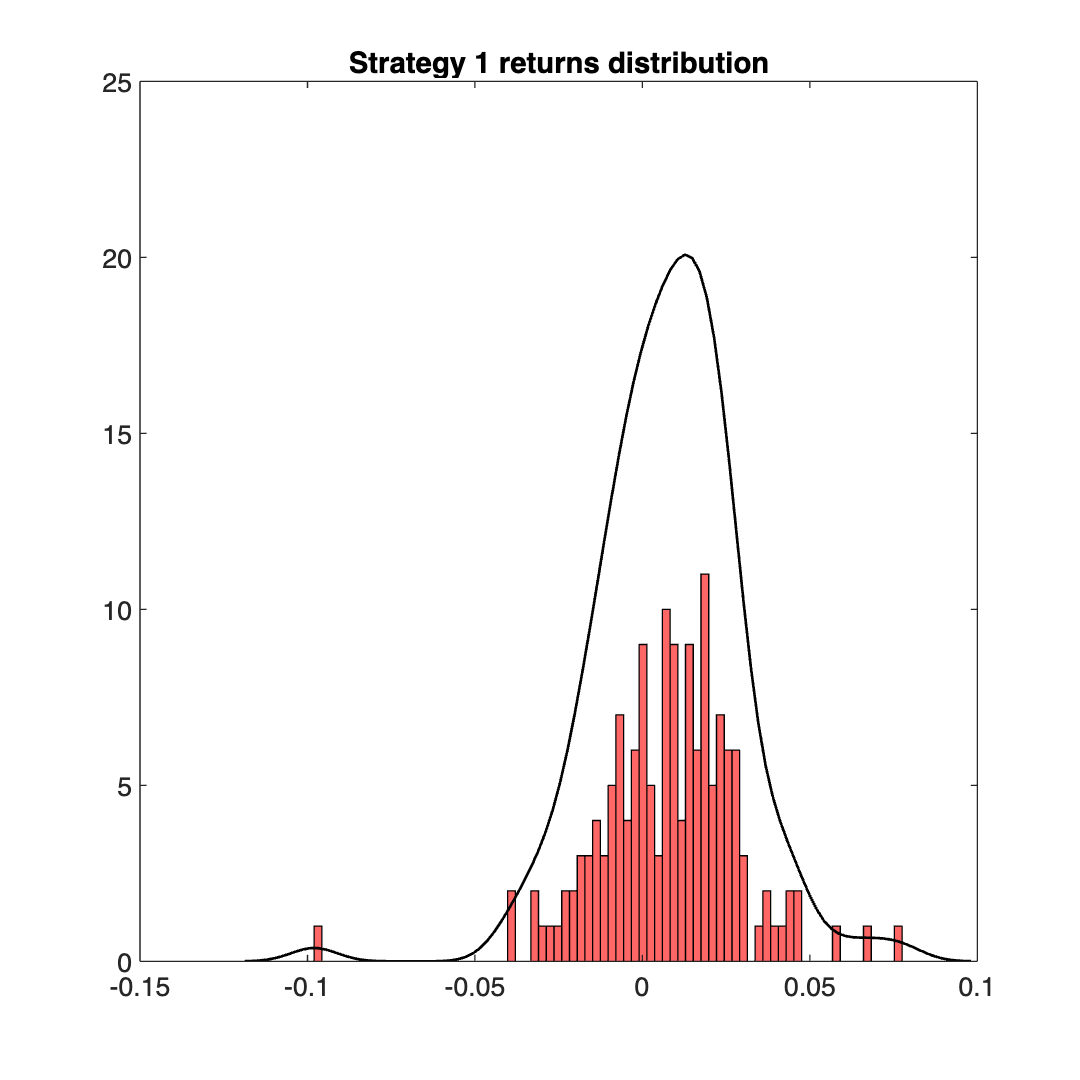

hold on;
[f, xi] = ksdensity(returns_st1);
plot(xi, f, 'LineWidth', 1, 'Color', 'k');
hold off;